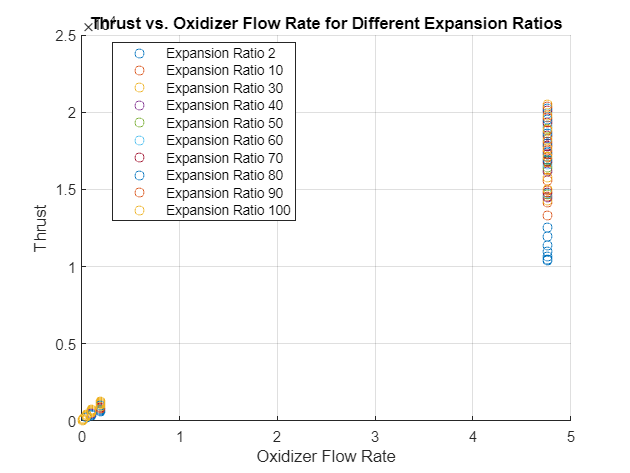

% Set the current working directory to the folder where the CSV file is located
cd('C:\Users\User\OneDrive - Victoria University of Wellington - STUDENT\B.Thrust Vectoring project\CODE\HybridRocketCode');

data = csvread('thrust_data.csv',1,0);


% Separate data based on ExpansionRatio
expansion_ratios = unique(data(:,1));

% Plot Thrust vs. OxidizerFlowRate for each ExpansionRatio
figure;
hold on;
for i = 1:length(expansion_ratios)
    ratio_data = data(data(:,1) == expansion_ratios(i), :);
    plot(ratio_data(:,2), ratio_data(:,3), 'o', 'DisplayName', ['Expansion Ratio ' num2str(expansion_ratios(i))]);
end

% Add labels and legend
xlabel('Oxidizer Flow Rate');
ylabel('Thrust');
title('Thrust vs. Oxidizer Flow Rate for Different Expansion Ratios');
legend('Location', 'best');
grid on;
hold off;